% This is the CPX1 Matlab Live Script - SIGNAL x2
% This file analyzes the first signal, x2
%
% Note that this was written as a live script, and thus prints values and
% plots to the screen for easy access
% 
% While writing a function would have enabled code to be reused, it was
% determined that the more important factor was easy accessibility to the
% plots, and any function would have required a large number of input
% values
%
% See the other files for the analysis of x3 and x4, the files were
% separated due to the intense memory requirements to display all of the
% plots
%
% Almost all plots have the frequency bins above the time/frequency values,
% as that enabled easy zooming in

% ================ Setup ================ %

cd("C:\Users\C25Dante.Cometto\OneDrive - afacademy.af.edu\Documents\1 Important\3 School 2024F\5 ECE 434\CPX2")
load cpx2.bin -mat
who


Your variables are:

Fs             Fs_x3          Fs_x4          Fs_x7          Fs_x8          H              K1             K2             K3             K4             N              X1             X1db           X3             X3db           X4             X4db           X7             X7db           X8             X8db           a              adb            alpha          ans            b              c              color1         color2         color3         color4         color5         correctValues  den_x1         den_x8         df1            df3            df4            df7            df8            dt1            dt3            dt4            dt7            dt8            errors         f              f1             f3             f4             f7             f8             fX1            fX1db          fX3            fX3db          fX4            fX4db          fX7            fX7db          fX8            fX8db          filterx7       fpts           fx1            fx3

Fs

Fs = 8000


color1 = "#77A890"

color1 = "#77A890"

color2 = "#26503C"

color2 = "#26503C"

color3 = "#F9F5E9"

color3 = "#F9F5E9"

color4 = "#9E816B"

color4 = "#9E816B"

color5 = "#C15441"

color5 = "#C15441"

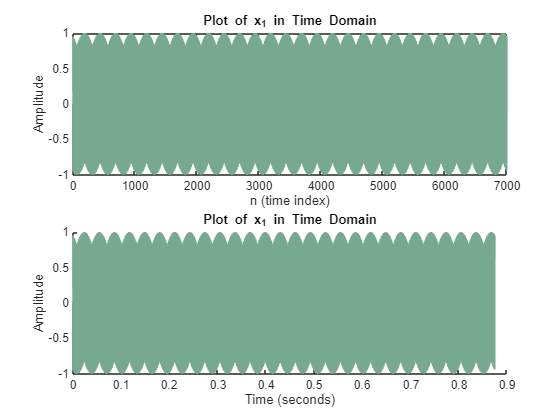

% =========================== For signal x1 ===========================
x1;
n1 = 0:length(x1)-1;
dt1 = 1/Fs;
t1 = n1*dt1;
X1 = fft(x1);
k1 = n1;
df1 = Fs/length(k1); % Fs/N
f1 = k1*df1;
X1db = 20*log10(abs(X1)/max(abs(X1)));

% ===== Begin by plotting in time domain =====
figure
subplot(2,1,1)
plot(n1,x1,"Color",color1)
title("Plot of x_1 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t1,x1,"Color",color1)
title("Plot of x_1 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

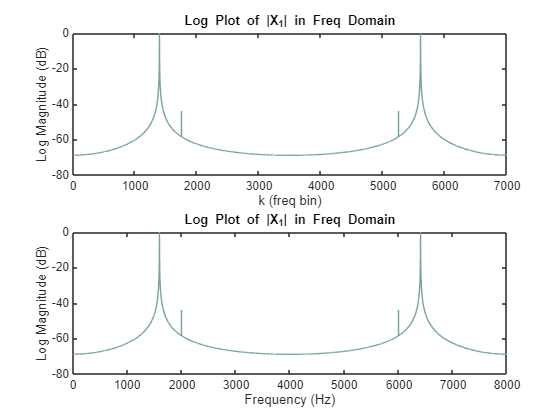


% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k1,X1db,"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f1,X1db,"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Zoom in
a = 1350

a = 1350

b = 1800

b = 1800

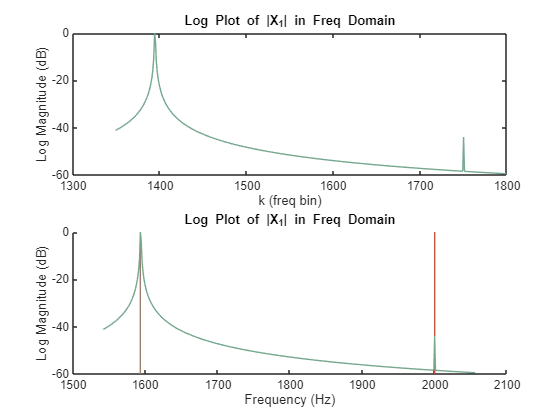


figure
subplot(2,1,1)
plot(k1(a:b),X1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([1593 1593],[-60 0],"Color",color4)
plot([2000 2000],[-60 0],"Color",color5)
plot(f1(a:b),X1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% => Freqs are at 1593 Hz and 2000 Hz

sound(x1)

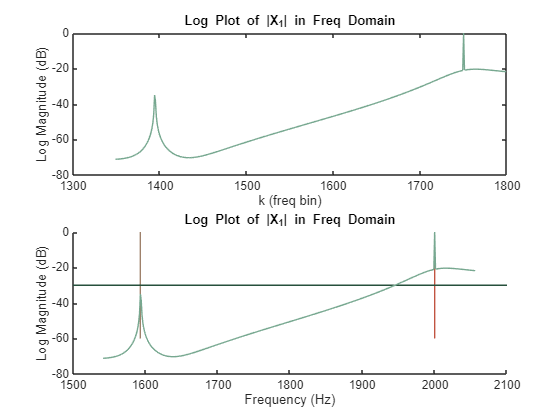

% Now, apply filter for x1
load filter_x1.bin -mat

fx1 = filter(num_x1,den_x1,x1);
fX1 = fft(fx1);
fX1db = 20*log10(abs(fX1)/max(abs(fX1)));

% Changelog:
% v1 - just over -30dB, order 7
% v2 - well below -30db, order 7

% And plot again

figure
subplot(2,1,1)
plot(k1(a:b),fX1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([1593 1593],[-60 0],"Color",color4)
plot([2000 2000],[-60 0],"Color",color5)
plot([1500 2100],[-30 -30],"Color",color2)
plot(f1(a:b),fX1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% sound is now the higher tone
sound(100*fx1)

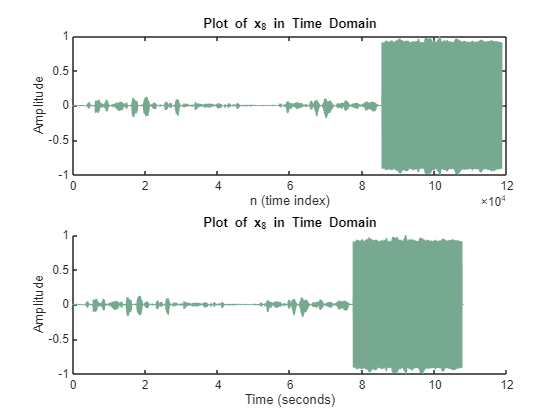

% =========================== For signal x8 ===========================
% Fix FS!!!!
x8;
n8 = 0:length(x8)-1;
dt8 = 1/Fs_x8;
t8 = n8*dt8;
X8 = fft(x8);
k8 = n8;
df8 = Fs_x8/length(k8); % Fs/N
f8 = k8*df8;
X8db = 20*log10(abs(X8)/max(abs(X8)));

% ===== Begin by plotting in time domain =====
figure
subplot(2,1,1)
plot([82500 82500],[-0.5 0.5],"Color",color5)
plot(n8,x8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t8,x8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

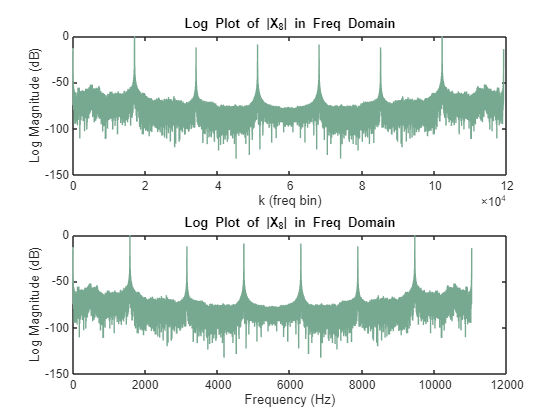


% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k8,X8db,"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f8,X8db,"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

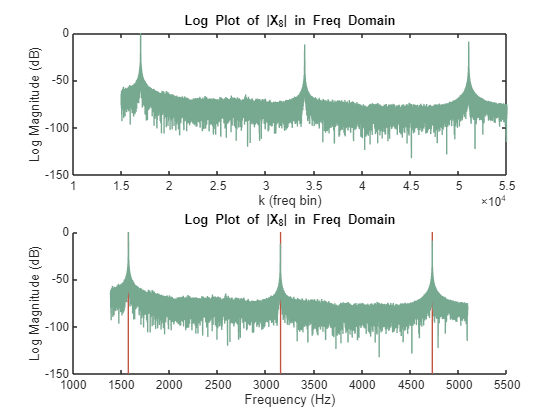


% Zoom in and label
a = 15000;
b = 55000;

t1 = 1142*11025/8000;
t2 = 2287*11025/8000;
t3 = 3429*11025/8000;

figure
subplot(2,1,1)
plot(k8(a:b),X8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([t1 t1],[-150 0],"Color",color5)
plot([t2 t2],[-150 0],"Color",color5)
plot([t3 t3],[-150 0],"Color",color5)
plot(f8(a:b),X8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Calculate normalized angular freq for pole-zero plot
w1 = t1/Fs_x8*2*pi

w1 = 0.8969

w2 = t2/Fs_x8*2*pi

w2 = 1.7962

w3 = t3/Fs_x8*2*pi

w3 = 2.6931

w1/2

ans = 0.4485

(w1+w2)/2

ans = 1.3466

(w2+w3)/2

ans = 2.2447

(w3+pi)/2

ans = 2.9174


sound(x8,Fs_x8)
% It's been 8 years upon a project for extracting sunbeams out of cucumbers.
%  He told me he did not doubt that in 8 years more ------

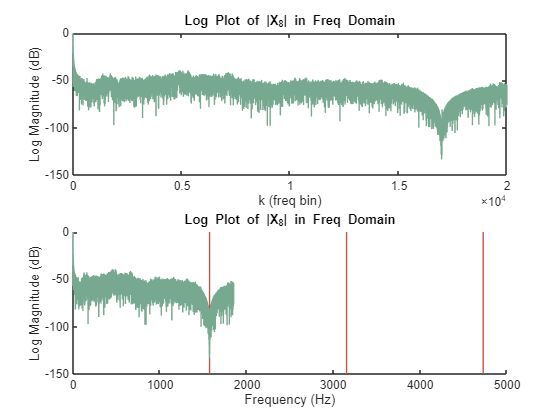

% Now, apply filter for x8
load filter_x8.bin -mat

fx8 = filter(num_x8,den_x8,x8);
fX8 = fft(fx8);
fX8db = 20*log10(abs(fX8)/max(abs(fX8)));

% Changelog:
% v1 - just barely missed the tones, looks like too high on all three, order 6 
% v2 - much better, but still not perfectly clear and can hear a tone, order 6
% v3 - can almost hear everything, still one tone, order 6
% v4 - removes tones better, but garbles audio, order 12
% v5 - beautifully removes tones, but audible clicks.  Order 12

% And plot again

figure
subplot(2,1,1)
plot(k8(a:b),fX8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([t1 t1],[-150 0],"Color",color5)
plot([t2 t2],[-150 0],"Color",color5)
plot([t3 t3],[-150 0],"Color",color5)
plot(f8(a:b),fX8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

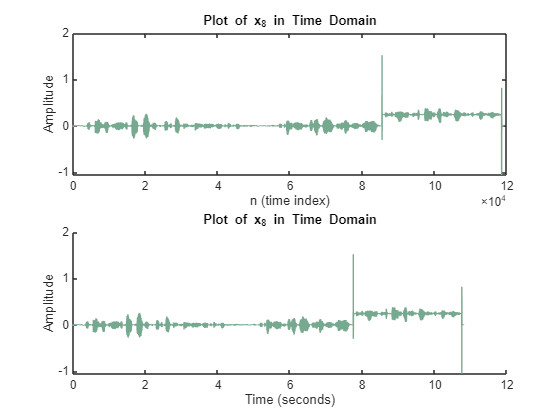


% And time plot too
figure
subplot(2,1,1)
plot(n8,fx8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t8,fx8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

% could work on smoothing out that click and amplitude difference... is
% that DC interference?  Oh, a tone at DC?  Yes, there is a tone at DC.
% Minimizes order to not remove, all information still gotten

% sound is now the higher tone
sound(fx8,Fs_x8)
% It's been 8 years upon a project for extracting sunbeams out of cucumbers.
%  He told me he did not doubt that in 8 years more he should be able to supply the governor's gardens with sunshine

% Google: https://brainly.com/question/2233369
% He has been eight years upon a project for extracting sunbeams out of cucumbers... 
% He told me, he did not doubt, that, in eight years more, he should be able to supply the governor’s gardens with sunshine

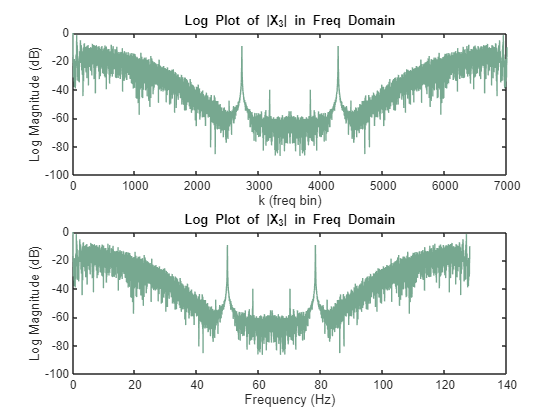

% x3 - ECG

% =========================== For signal x3 ===========================
x3;
n3 = 0:length(x3)-1;
dt3 = 1/Fs_x3;
t3 = n3*dt3;
X3 = fft(x3);
k3 = n3;
df3 = Fs_x3/length(k3); % Fs/N
f3 = k3*df3;
X3db = 20*log10(abs(X3)/max(abs(X3)));

% ===== Begin by plotting in time domain =====

% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k3,X3db,"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f3,X3db,"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Note that contamination occurs at 50 Hz


% Zoom in
a = 2500

a = 2500

b = 2900

b = 2900

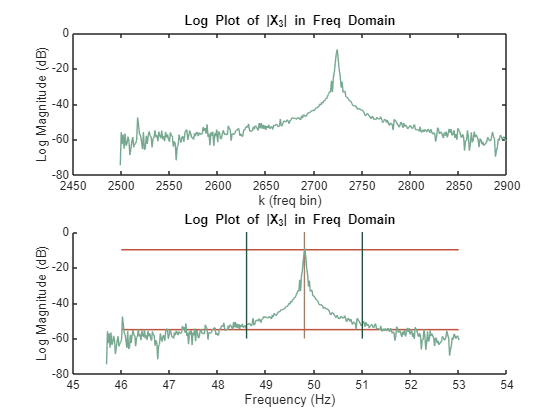


figure
subplot(2,1,1)
plot(k3(a:b),X3db(a:b),"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([49.8 49.8],[-60 0],"Color",color4)
plot([46 53],[-10 -10],"Color",color5)
plot([46 53],[-55 -55],"Color",color5)
plot(f3(a:b),X3db(a:b),"Color",color1)
plot([48.6 48.6],[-60 0],"Color",color2)
plot([51 51],[-60 0],"Color",color2)
title("Log Plot of |X_3| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Centered around 49.8 Hz
% Reaches from 48.6 to 51
% Peak is at -15 db
% Data is at -55 db

% Now, apply filter for x3
load filter_x3.bin -mat

fx3 = filter(num_x3,1,x3);
fX3 = fft(fx3);
fX3db = 20*log10(abs(fX3)/max(abs(fX3)));

% Changelog:
% v1 - took out way too much and super high order 252
% v2- better, cleans up data nicely, too destructive, 94
% v3 - doesn't remove peak, suppresses data too much, 24
% v4 - just barely removes too much, 66
% v5 - better, 76
% v6 - the -60db spike is clearly visible, 102
% v6b - better than v6, much more narrow effect 98 ^^ equiripple
% v7 - changed to LSE, not better, 90
% currently using v6b

% And plot again
a = 2500

a = 2500

b = 2900

b = 2900


figure
subplot(2,1,1)
plot(k3(a:b),X3db(a:b),"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([49.8 49.8],[-60 0],"Color",color4)
plot([46 53],[-10 -10],"Color",color5)
plot([46 53],[-55 -55],"Color",color5)
plot(f3(a:b),fX3db(a:b),"Color",color1)
plot([48.6 48.6],[-60 0],"Color",color2)
plot([51 51],[-60 0],"Color",color2)
title("Log Plot of |X_3| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

% And time plot too
figure
subplot(2,1,1)
plot(n3,x3,"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t3,fx3,"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

% zoom in

a = 10

a = 10

b = 266

b = 266


figure
subplot(2,1,1)
plot(n3(a:b),x3(a:b),"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t3(a:b),fx3(a:b),"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

% x4 - wideband jamming

% =========================== For signal x4 ===========================
Fs_x4

Fs_x4 = 22050

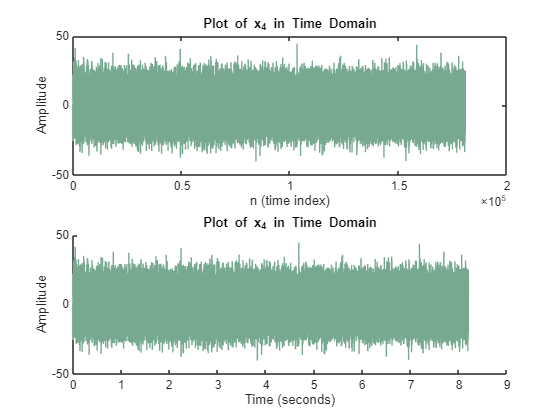

x4;
n4 = 0:length(x4)-1;
dt4 = 1/Fs_x4;
t4 = n4*dt4;
X4 = fft(x4);
k4 = n4;
df4 = Fs_x4/length(k4); % Fs/N
f4 = k4*df4;
X4db = 20*log10(abs(X4)/max(abs(X4)));

% ===== Begin by plotting in time domain =====

figure
subplot(2,1,1)
plot(n4,x4,"Color",color1)
title("Plot of x_4 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t4,x4,"Color",color1)
title("Plot of x_4 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

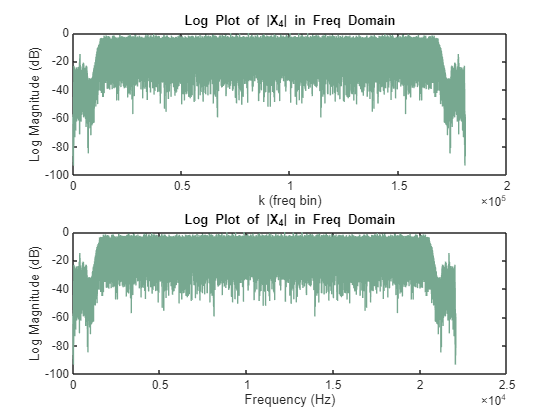


% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k4,X4db,"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f4,X4db,"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Note that contamination occurs at 50 Hz


% Zoom in
a = 1

a = 1

b = 20000

b = 20000

c = 1100

c = 1100

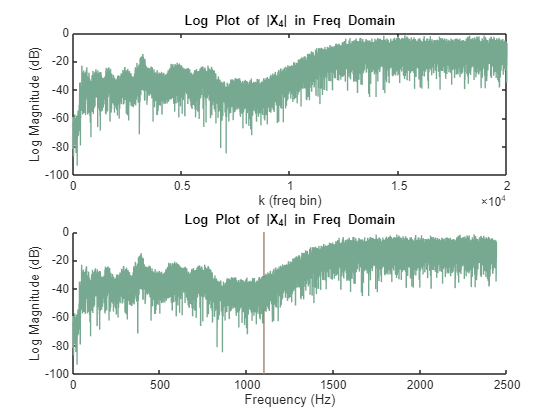


figure
subplot(2,1,1)
plot(k4(a:b),X4db(a:b),"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([c c],[-100 0],"Color",color4)
plot(f4(a:b),X4db(a:b),"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Jamming begins around 1100 -- should be enough to hear message
sound(x4, Fs_x4)

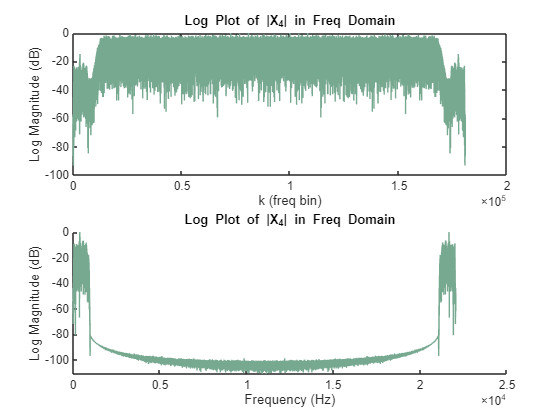

% Now, apply filter for x4
load filter_x4.bin -mat

fx4 = filter(num_x4,1,x4);
fX4 = fft(fx4);
fX4db = 20*log10(abs(fX4)/max(abs(fX4)));

% Changelog:
% v1 - missed beginning of static order 21
% v2 - still hear static and sounds like a can order 218
% v3 - so close to hearing it, weird humm in background, order 341
% v4 - humming around 1.1khz+, order 402
% v5 - a little humming and still cannot hear order 161
% v6 - humming gone ish, sounds bad order 161
% v7 - no humming at all, still canny order 803
% v7b - a little humming, canny, order 803

% And plot again

figure
subplot(2,1,1)
plot(k4,X4db,"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot(f4,fX4db,"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

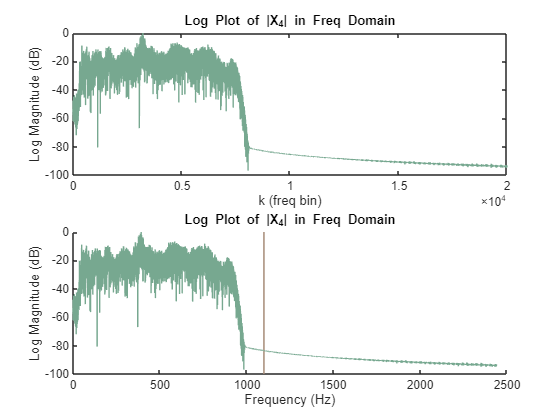


% Zoomed

figure
subplot(2,1,1)
plot(k4(a:b),fX4db(a:b),"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([c c],[-100 0],"Color",color4)
plot(f4(a:b),fX4db(a:b),"Color",color1)
title("Log Plot of |X_4| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

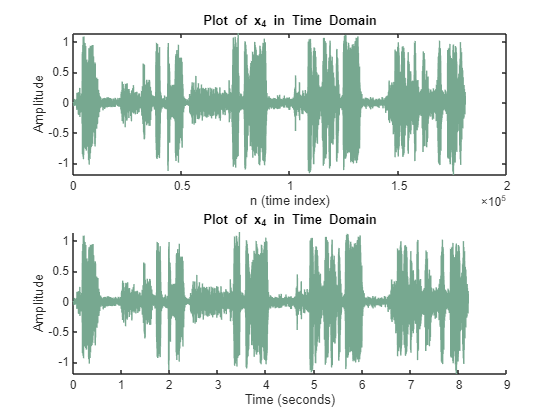




% And time plot too
figure
subplot(2,1,1)
plot(n4,fx4,"Color",color1)
title("Plot of x_4 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t4,fx4,"Color",color1)
title("Plot of x_4 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off


% Play sound
sound(fx4,Fs_x4)

% v6: huh, [what is that] the light, crush your enemies, [it is given before
% you], [and walalalalalanight]

% v7b: <drum> huh, <drum> [what if that's] the light <drum>, cwush your enemies, <drum> [it <drum> is given before
% you],  [and wala <drum> lalalalanight]

% Googled v6 -- conan the barbarian says in
% https://www.youtube.com/watch?v=V30tyaXv6EI at 0:23
% Conan, what is best in life? "to crush your enemies, see them driven before you, and to hear the
% lametations of their women"

% x7 - multiband filter and tones

% =========================== For signal x7 ===========================
Fs_x7

Fs_x7 = 20000

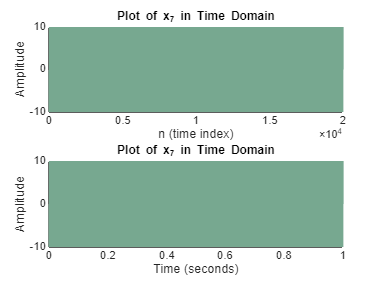

x7;
n7 = 0:length(x7)-1;
dt7 = 1/Fs_x7;
t7 = n7*dt7;
X7 = fft(x7);
k7 = n7;
df7 = Fs_x7/length(k7); % Fs/N
f7 = k7*df7;
X7db = 20*log10(abs(X7)/max(abs(X7)));

% ===== Begin by plotting in time domain =====

figure
subplot(2,1,1)
plot(n7,x7,"Color",color1)
title("Plot of x_7 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t7,x7,"Color",color1)
title("Plot of x_7 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

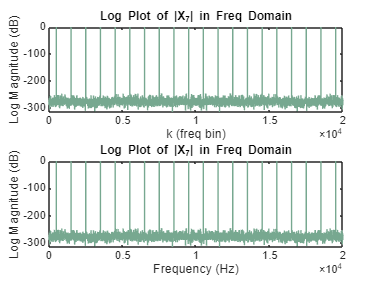


% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k7,X7db,"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f7,X7db,"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Note that contamination occurs at 50 Hz


% Zoom in
a = 1

a = 1

b = length(x7)/2

b = 10000

c = 1100

c = 1100

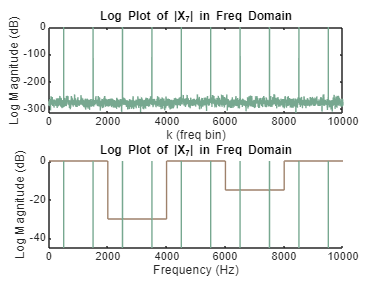


figure
subplot(2,1,1)
plot(k7(a:b),X7db(a:b),"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on

plot([0 2000],[0 0],"Color",color4)
plot([2000 2000],[0 -30],"Color",color4)
plot([2000 4000],[-30 -30],"Color",color4)
plot([4000 4000],[-30 0],"Color",color4)
plot([4000 6000],[0 0],"Color",color4)
plot([6000 6000],[0 -15],"Color",color4)
plot([6000 8000],[-15 -15],"Color",color4)
plot([8000 8000],[-15 0],"Color",color4)
plot([8000 10000],[0 0],"Color",color4)

plot(f7(a:b),X7db(a:b),"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")
ylim([-45 0])
hold off


% Normalized angular frequency

figure
figure
subplot(2,1,1)
plot(k7(a:b),X7db(a:b),"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on

plot(2*[0 2000/(Fs_x7)],[0 0],"Color",color4)
plot(2*[2000/(Fs_x7) 2000/(Fs_x7)],[0 -30],"Color",color4)
plot(2*[2000/(Fs_x7) 4000/(Fs_x7)],[-30 -30],"Color",color4)
plot(2*[4000/(Fs_x7) 4000/(Fs_x7)],[-30 0],"Color",color4)
plot(2*[4000/(Fs_x7) 6000/(Fs_x7)],[0 0],"Color",color4)
plot(2*[6000/(Fs_x7) 6000/(Fs_x7)],[0 -15],"Color",color4)
plot(2*[6000/(Fs_x7) 8000/(Fs_x7)],[-15 -15],"Color",color4)
plot(2*[8000/(Fs_x7) 8000/(Fs_x7)],[-15 0],"Color",color4)
plot(2*[8000/(Fs_x7) 10000/(Fs_x7)],[0 0],"Color",color4)

plot(2*f7(a:b)/(Fs_x7),X7db(a:b),"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")
ylim([-45 0])
hold off


% Design filter
% Remez is the deprecated version of firpm, but they do the same thing

% v1, v2
% f = 2*[0 1900 2100 3900 4100 5900 6100 7900 8100 10000]/(Fs_x7)
% a = 10.^([0 0 -30 -30 0 0 -15 -15 0 0]/20)
% b = firpm(200,f,a);
% n = 512

% new
f = 2*[500 1500 2500 3500 4500 5500 6500 7500 8500 9500]/(Fs_x7)

f =     0.0500    0.1500    0.2500    0.3500    0.4500    0.5500    0.6500    0.7500    0.8500    0.9500


a = 10.^([0 0 -30 -30 0 0 -15 -15 0 0]/20)

a =     1.0000    1.0000    0.0316    0.0316    1.0000    1.0000    0.1778    0.1778    1.0000    1.0000


num_x7 = firpm(51,f,a);

length(num_x7)

ans = 52


[h,w] = freqz(num_x7,1,512);

adb = 20*log10(abs(a)/max(abs(a)))

adb =      0     0   -30   -30     0     0   -15   -15     0     0


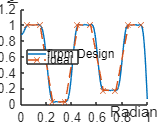

hdb = 20*log10(abs(h)/max(abs(h)));



figure
hold on
plot(w/pi,abs(h))
plot(f,a,'x--')
legend('firpm Design', 'ideal','Location','best')
xlabel 'Radian Frequency (\omega/\pi)', ylabel 'Magnitude'
title("Freq Response")

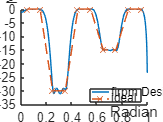


figure
hold on
plot(w/pi,hdb)
plot(f,adb,'x--')
legend('firpm Design', 'ideal','Location','best')
xlabel 'Radian Frequency (\omega/\pi)', ylabel 'Magnitude'
title("Log Freq Response")

% Apply filter to x7

fx7 = filter(num_x7,1,x7);
fX7 = fft(fx7);
fX7db = 20*log10(abs(fX7)/max(abs(fX7)));

% Changelog:
% v1 - order 200: max 0.0855  mean 0.0197
% v2 - order 20:  max 11.019  mean 2.9625
% v3 - order 30:  max 5.7836  mean 1.6085
% v4 - order 40:  max 2.4776  mean 0.6276
% v5 - order 50:  max 1.0414  mean 0.2672
% v6 - order 60:  max 0.3888  mean 0.1004
% v7 - order 55:  max 0.7200  mean 0.1844
% v8 - order 52:  max 0.4785  mean 0.1058
% v9 - order 51:  max 0.9382  mean 0.1933


% Calculate error
tones = ((1:10)-1)*1000+501;
toneValues = fX7db(tones);
correctValues = [0 0 -30 -30 0 0 -15 -15 0 0];
errors = abs(correctValues - toneValues)

errors =     0.0676    0.0638    0.9382    0.3982    0.0658         0    0.1085    0.2256    0.0011    0.0639



maxError = max(errors)

maxError = 0.9382

meanError = mean(errors)

meanError = 0.1933


% And plot again
a = 1

a = 1

b = length(x7)/2

b = 10000

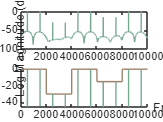



figure
subplot(2,1,1)
plot(k7(a:b),fX7db(a:b),"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on

plot([0 2000],[0 0],"Color",color4)
plot([2000 2000],[0 -30],"Color",color4)
plot([2000 4000],[-30 -30],"Color",color4)
plot([4000 4000],[-30 0],"Color",color4)
plot([4000 6000],[0 0],"Color",color4)
plot([6000 6000],[0 -15],"Color",color4)
plot([6000 8000],[-15 -15],"Color",color4)
plot([8000 8000],[-15 0],"Color",color4)
plot([8000 10000],[0 0],"Color",color4)

plot(f7(a:b),fX7db(a:b),"Color",color1)
title("Log Plot of |X_7| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")
ylim([-45 0])
hold off